A = imread('ENV2_3D_01.png');
size(A)

ans =    232   366     3


A_gray = rgb2gray(A);
[nr nc] = size(A_gray)

nr = 232

nc = 366

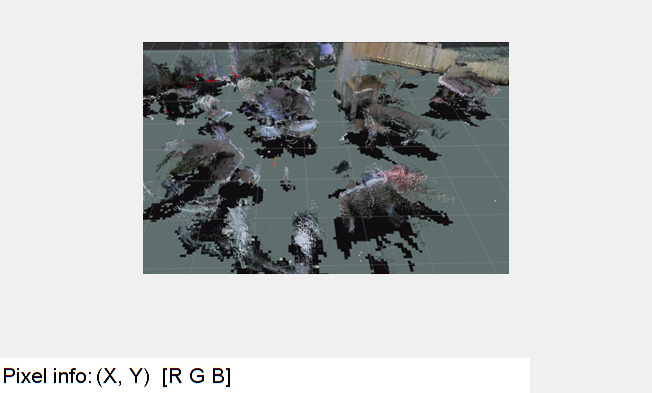

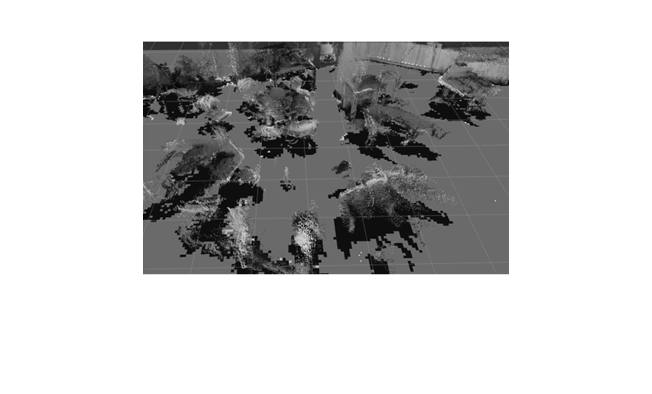

imwrite(A_gray, 'ENV2_3D_01_gray.png');
Sx=[-1 0 1; -2 0 2; -1 0 1]; % Sobel operator
Sy=[-1 -2 -1; 0 0 0; 1 2 1]; % Sobel operator
Ax=imfilter(double(A_gray), Sx);
Ay=imfilter(double(A_gray), Sy);
figure, imshow(A), impixelinfo
figure, imshow(A_gray), impixelinfo

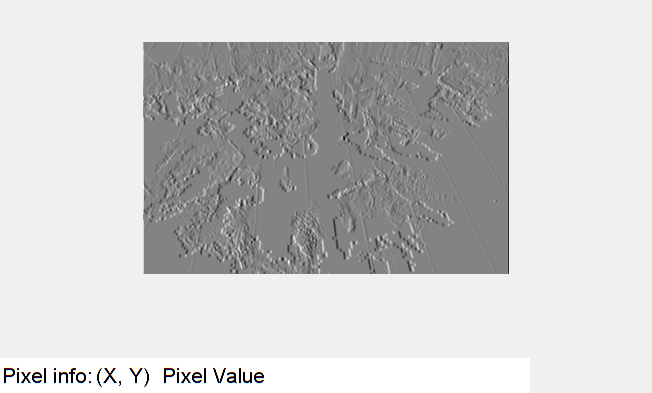

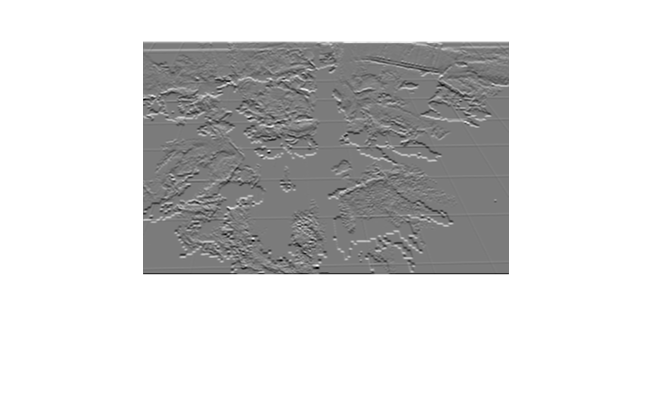

figure, imshow(mat2gray(Ax)), impixelinfo
figure, imshow(mat2gray(Ay)), impixelinfo